# Examples 6.19 and 6.21: 2D Filters and Fourier Transform of an Image

Note: this script reproduces Examples 6.19 and 6.21 (Section 6.3.5) of **Statistics for Chemical Engineers**: Sobel and Gaussian filters applied to an image, directly and with the convolution theorem. Victor Z UW-Madison, 2020 use Sobel and Gaussian filters

clc; clear all; close all hidden

## Image

reading and converting the image

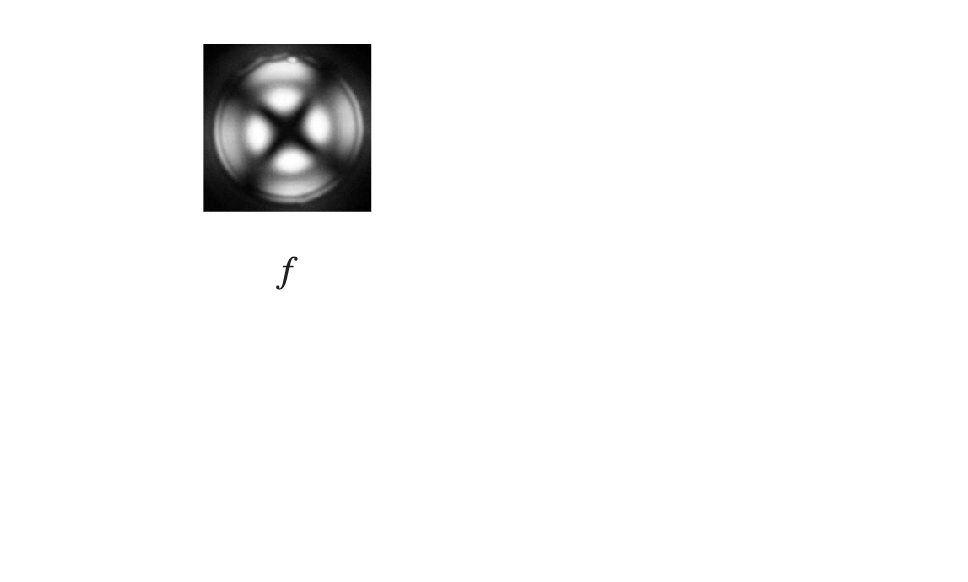

inImage=imread('./Data/droplet1g.jpg');
f=double(inImage); 

figure(1)
subplot(2,2,1)
imshow(uint8(f),[]);
box off
xlabel('$f$','Interpreter','Latex','FontSize',14)

## Sobel filter (edges)

apply Sobel filter in vertical direction

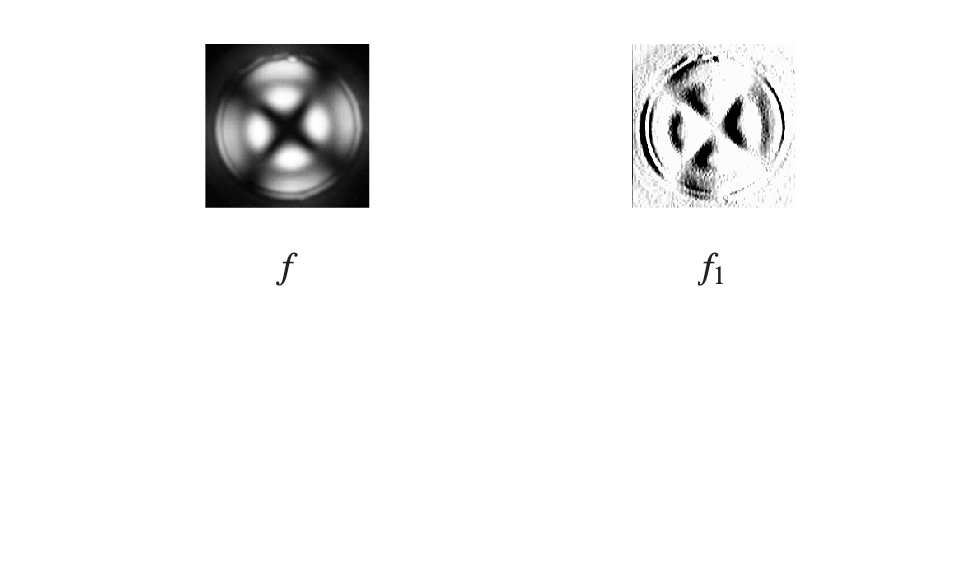

g=[1 2 1; 0 0 0; -1 -2 -1]';
fn=conv2(f,g,'same');
% use reverse color map to better visualize gradients
c=linspace(0.99,0.0,64)';
C=[c,c,c];
subplot(2,2,2)
imshow(uint8(fn),C);
box off
xlabel('$f_1$','Interpreter','Latex','FontSize',14)

## Gaussian filters

apply Gaussian filter (low sigma)

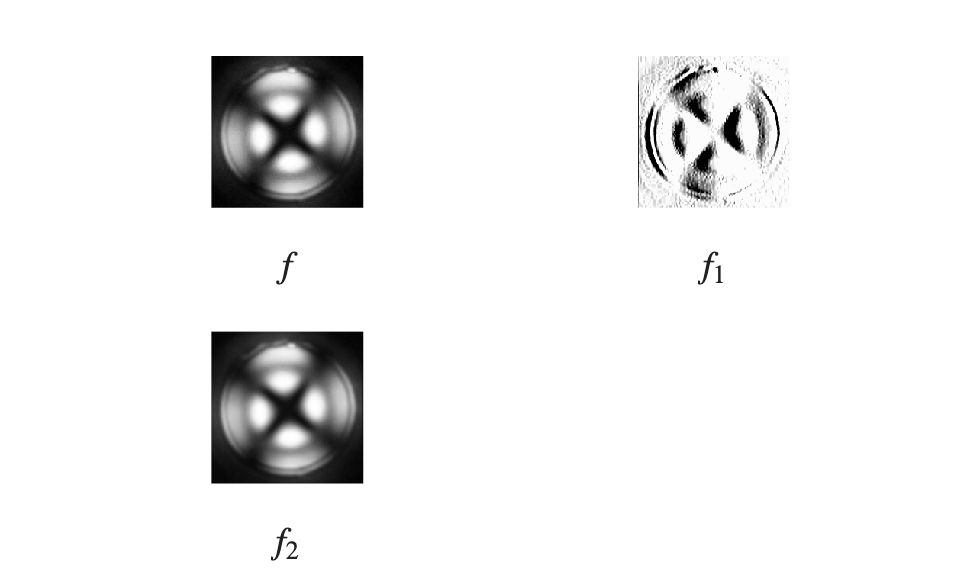

sigma=1;
hsize=100;
g = fspecial('gaussian',hsize,sigma);

fn=conv2(f,g,'same');

subplot(2,2,3)
imshow(uint8(fn));
box off
xlabel('$f_2$','Interpreter','Latex','FontSize',14)

## apply Gaussian filter (high sigma)

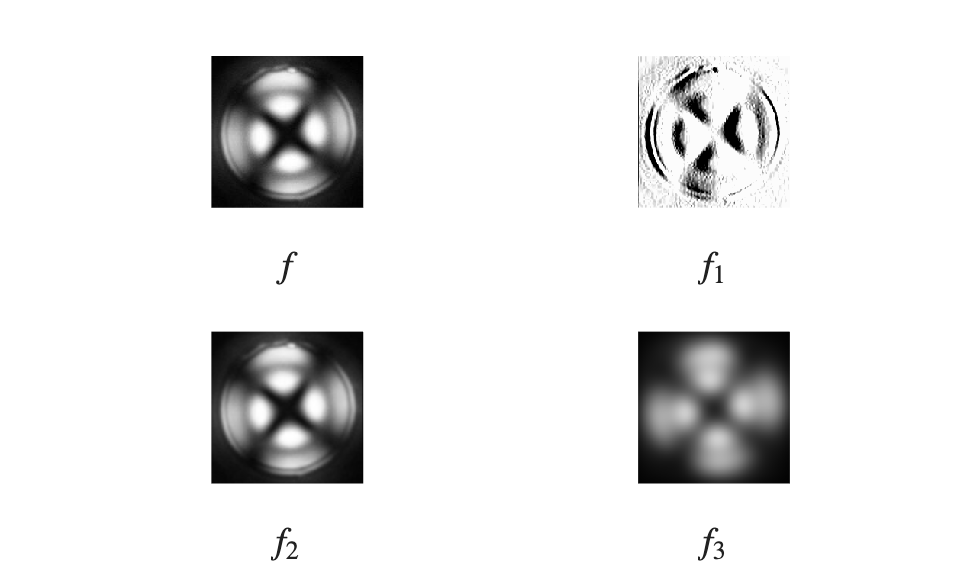

sigma=10;
hsize=100;
g = fspecial('gaussian',hsize,sigma);
fn2=conv2(f,g,'same');
subplot(2,2,4)
imshow(uint8(fn2));
box off
xlabel('$f_3$','Interpreter','Latex','FontSize',14)

print -depsc ch6_image_2Dfilters.eps

## Filtering in the frequency domain (Example 6.21)

apply Gaussian filter using convolution theorem

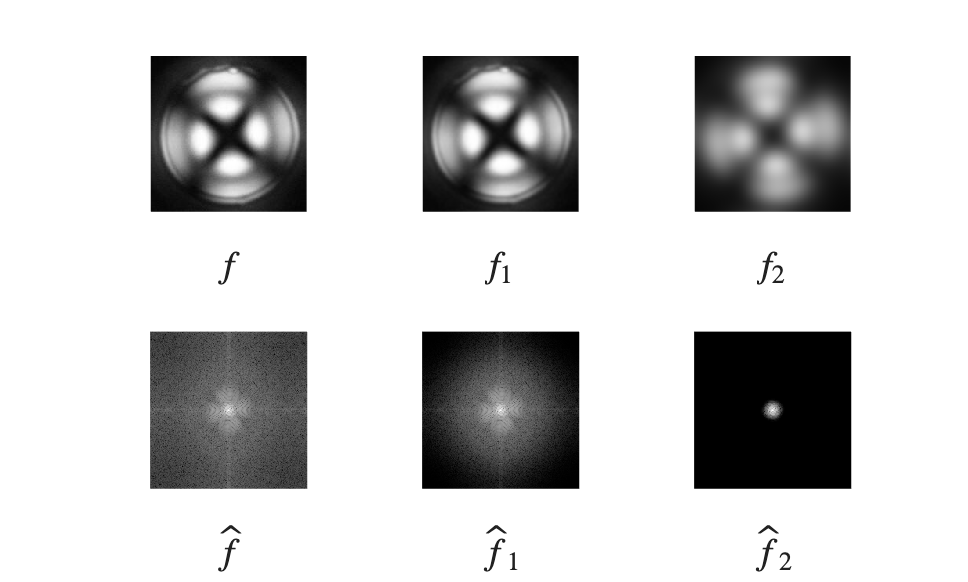

figure(3)
subplot(2,3,1)
imshow(uint8(f));
box off
xlabel('$f$','Interpreter','Latex','FontSize',14)

subplot(2,3,4)
F=fft2(f);

S=fftshift(log(1+abs(F)));

imshow(S,[])
xlabel('$\hat{f}$','Interpreter','Latex','FontSize',14)

% eliminate high frequencies (small sigma)
sigma=1;
hsize=length(f);
g = fspecial('gaussian',hsize,sigma);

subplot(2,3,5)

ff=fft2(f).*fft2(g);

S=fftshift(log(1+abs(ff)));
imshow(S,[])
xlabel('$\hat{f}_1$','Interpreter','Latex','FontSize',14)

fn=ifft2(ff);

fn=real(fftshift(fn));
subplot(2,3,2)
imshow(uint8(fn));
box off
xlabel('$f_1$','Interpreter','Latex','FontSize',14)

% eliminate low frequencies (large sigma)
sigma=10;
hsize=length(f);
g2 = fspecial('gaussian',hsize,sigma);

subplot(2,3,6)
ff=fft2(f).*fft2(g2);
S=fftshift(log(1+abs(ff)));
imshow(S,[])
xlabel('$\hat{f}_2$','Interpreter','Latex','FontSize',14)

fn=ifft2(ff);
fn=real(fftshift(fn));
subplot(2,3,3)
imshow(uint8(fn));
box off
xlabel('$f_2$','Interpreter','Latex','FontSize',14)
print -depsc ch6_2d_fourier_image.eps

## Note

As in the book, the Sobel filter reveals edges and the Gaussian filter smooths the image; a small part of the spectrum is enough to capture its coarse features.